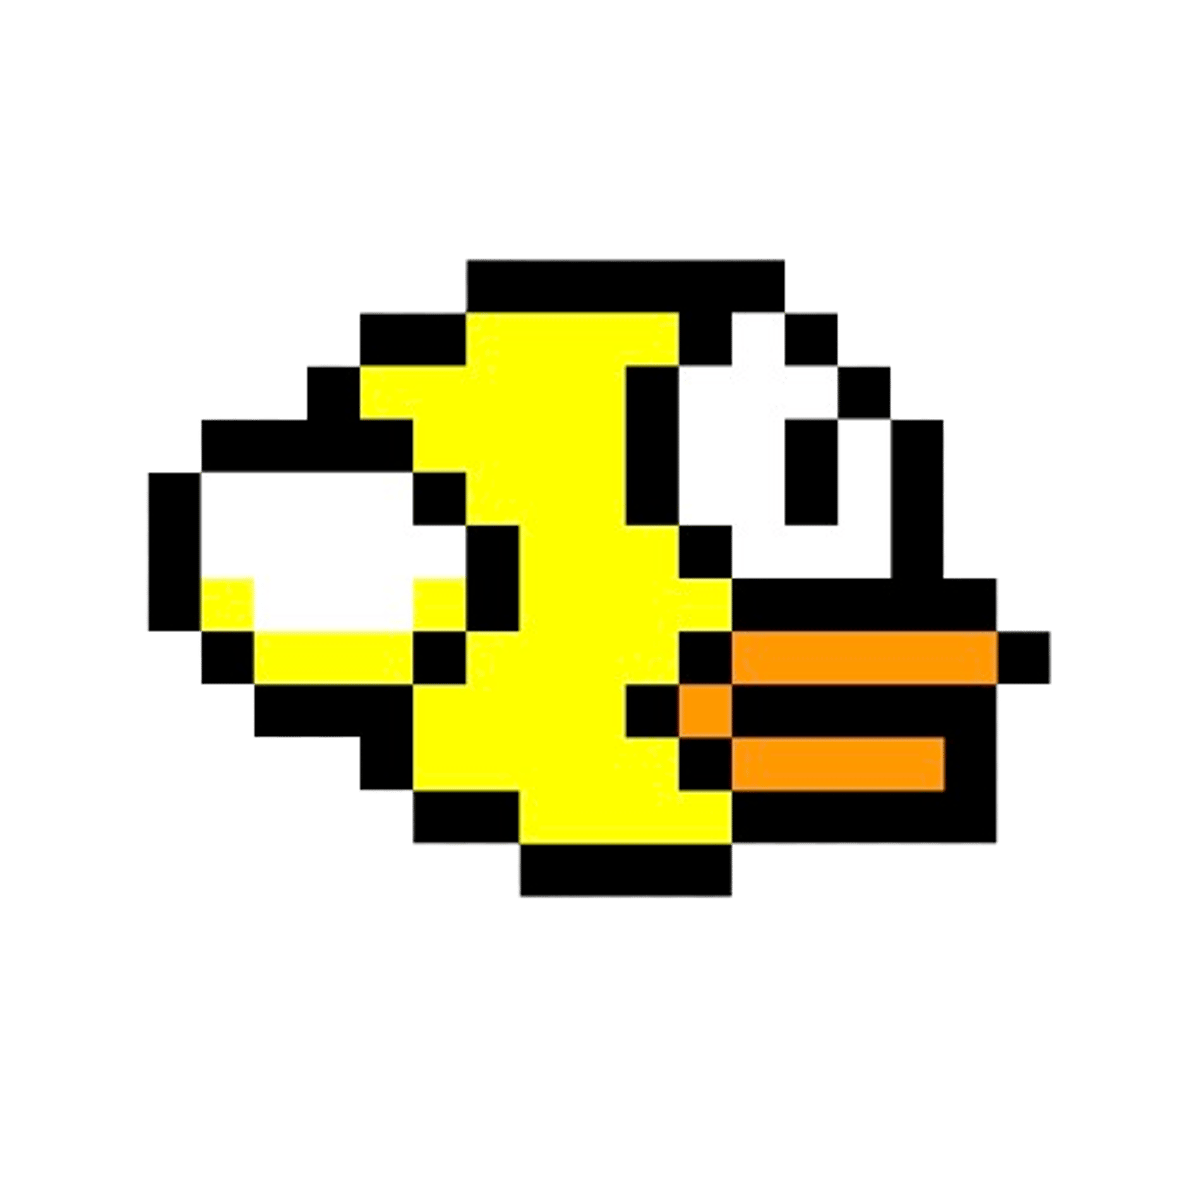

# Project: Altitude control of a Flappy Bird robot

## Part 1: Modelling and performance specifications

## Project overview

You are tasked with designing an altitude (height) controller for a Flappy Bird robot. We are going to assume the robot only has a single controllable degree of freedom (that being up and down) and has a controlled constant lateral (forward) velocity that we do not need to worry about. As in the original game, the Flappy Bird robot will be required to move through a series of obstacles, with ever decreasing space allowance — see Figure 1.

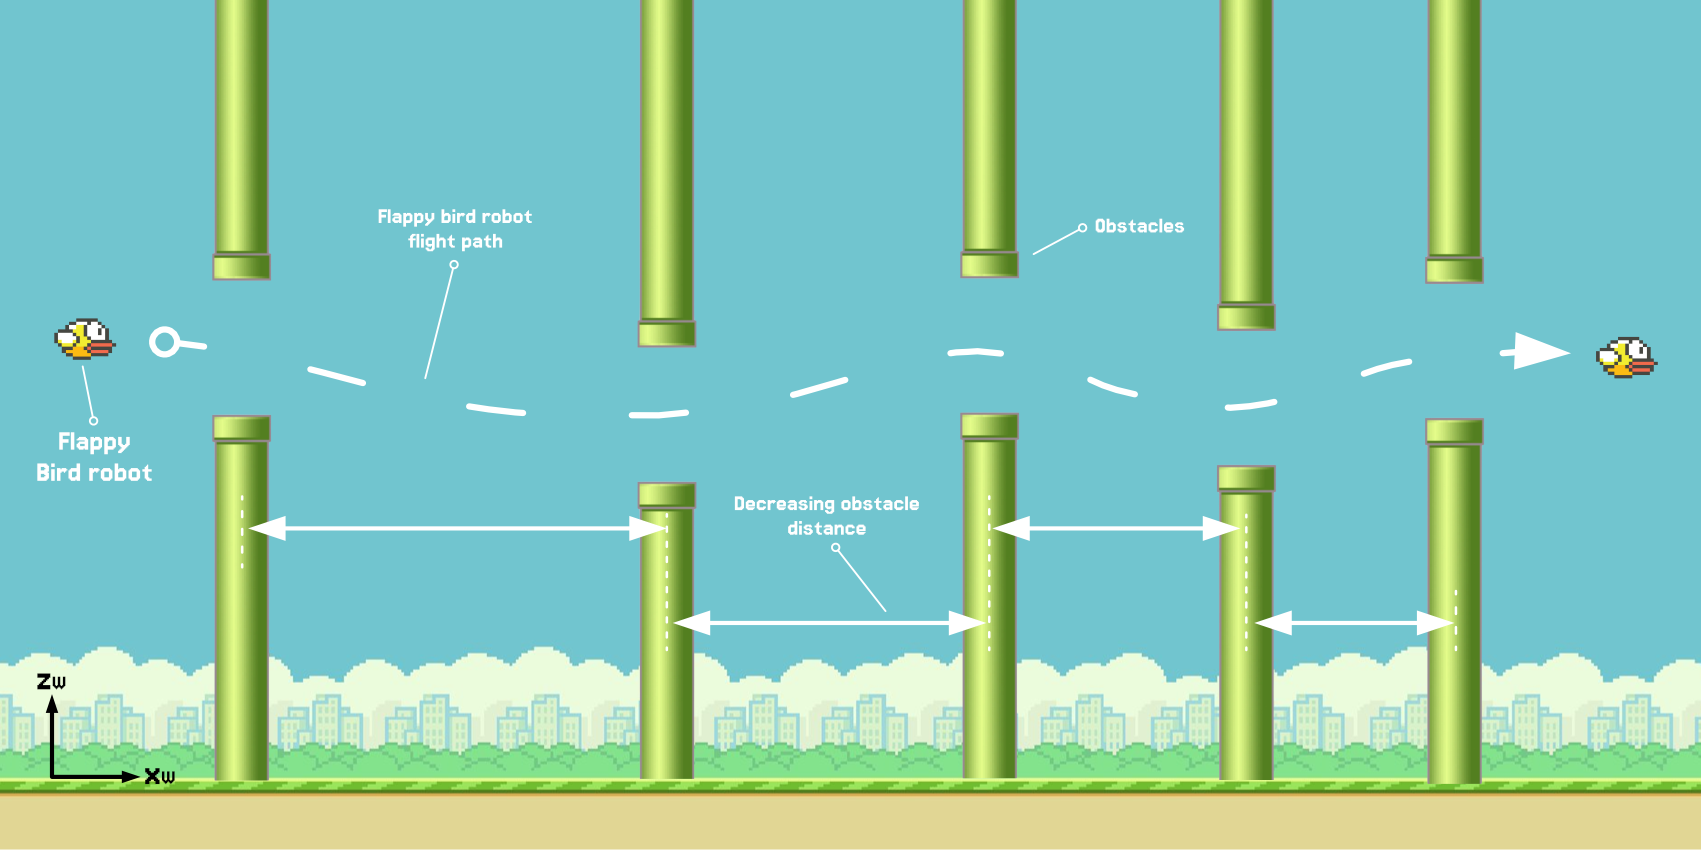

**Figure 1**: Image of Flappy Bird robot in action navigating the obstacle course.

The Flappy Bird game will run in MATLAB and can be called by running the code below. Note that you need to also enter your PeopleSoft ID (your seven-digit numerical identifier), as each student's Flappy Bird robot will have different dynamic behaviour. 

The Flappy Bird game is packaged within the attached MATLAB toolbox, `FlappyBirdPart1.mltbx`. To play the game, you must first install this toolbox. To do this, ensure your MATLAB working directory is set to the project folder and that the `.mltbx` file is located in this folder. Then, execute the following command:

matlab.addons.install('FlappyBirdPart1.mltbx');

To run the game, initialise the application with the following code. Ensure you fill in your personal PeopleSoftID number first.

PeopleSoftID = 0; %enter your seven-digit numerical ID
app = FlappyBirdPart1(PeopleSoftID);

Running this code opens the game's Graphical User Interface (GUI). To start playing, toggle the **Flappy Bird** switch from ***Exit*** to ***Play***. For now, you only have access to the open-loop mode, where you can use the keyboard to attempt to get your Flappy Bird robot through all the obstacles — feel free to play a bit and see how far you can get. In **Part 2**, you will automate the Flappy Bird robot so that you can sit back and relax while your feedback controller does all the work for you! To make the bird flap, press the *space bar*, the *W* key, or the *Up Arrow* key. You can also plot the bird's trajectory in real-time by toggling the **Trajectory Plot** slider to the ***On***.

To exit the game, first toggle the **Flappy Bird** switch back to ***Exit***. After the game window closes, execute the command below to close the application completely. 

delete(app)

The Flappy Bird's wings produce a controllable instantaneous bi-directional thrust that is used to move the robot up and down as required. A constant gravitational acceleration acts downwards on the Flappy Bird robot, which the controller needs to overcome in order to prevent the robot from falling to the ground. Additionally, aerodynamic drag, proportional to the robot's vertical velocity, affects the system response.

You are provided with the simplified dynamics of the Flappy Bird robot altitude below:


$$\begin{array}{rl} m a(t) &=f(t)-mg-bv(t),\\ 
\dot{v}(t) &=a(t),\\
\dot{z}(t) &=v(t),\\
\end{array}$$


where:

- $f(t)$ is the controllable vertical thrust produced by the wings, in $N$,

- $m$ is the mass of the Flappy Bird robot, in $kg$,

- $g$ is the gravitational acceleration, in $m.s^{-2}$,

- $b$ is the aerodynamic drag coefficient, in $N.s.m^{-1}$,

- $v(t)$ is the vertical velocity of the robot, in $m.s^{-1}$,

- $a(t)$ is the linear acceleration of the robot, in $m.s^{-2}$,

- $z(t)$is the height (altitude) of the robot above ground, in $m$.

Note also that $\{m,b,g\}>0$. We will assume for now that the Flappy Bird robot is initially at rest (on the ground and motionless) and this corresponds with $z(t)=0$. Note that while not explicitly captured in the dynamics above, the simulated Flappy Bird robot is unable to go to negative heights as a result of the ground ($z(t)\geq 0,~\forall t$). 

**Part 1** will focus on modelling our Flappy Bird robot, followed by determining the requisite closed-loop performance specifications to keep the Flappy Bird robot from crashing into any pillars. We will need this information in order to move to the control design in **Part 2**. 

## System modelling

We begin by determining a suitable mathematical model of our system, given dynamic knowledge of our system.

#### **  Question 1:** Provide a detailed block diagram of the Flappy Bird robot based on the information provided above. The block diagram must show the mapping from input signal $U(s)=F(s)$ to the altitude output signal, $Y(s)=Z(s)$, as well as the inclusion of the gravitational acceleration disturbance, $D(s)$. All system parameters, $\{m,b\}$, should be represented by blocks.

*Format: Your answer can be handwritten or completed using a graphical tool and should clearly show all relevant signal and parameter names. *

%Code block (if required)


#### **  Question 2:** Simplify your answer in Question 1 to a two-block system, where one block represents the collective transfer behaviour from $F(s)$ to $Z(s)$, described by $P(s)$, and the other block represents the transfer behaviour from the gravitational acceleration, $D(s)$, to $Z(s)$, described by $H(s)$. Include all working as part of your submission.

*Format: Your answer can be handwritten or completed using a graphical tool and should clearly show all relevant signal and parameter names. *

%Code block (if required)


## Performance specifications

In order to design an appropriate feedback controller, you will need to determine the requisite performance specifications for the Flappy Bird robot in order to *always* avoid hitting an obstacle. We will begin by assessing the steady-state error requirements. We desire precision control of the Flappy Bird robot, so we will target zero-error tracking at steady-state to both step-like reference signals and disturbances.

#### **  Question 3:** Determine the minimum type number required by the robot's controller in order to fully reject disturbances at steady-state.

%Code block (if required)


We will now focus on the transient design specifications. Based on modelling our Flappy Bird robot, it should be clear that our plant $P(s)$ is second-order. This means that the closed-loop system, after designing $G(s)$, will be at least second order. As such, we will use design specifications relating to second-order systems (see **Chapter 11** for more information) With reference to Figure 2, our Flappy Bird robot moves laterally at constant speed of $5$ m/s and is always issued step commands halfway between each set of obstacles, with the desired path also passing exactly in the middle of each gap. The goal is for the robot to follow the step commands sufficiently, such that the worst-case overshoot and settling time is adhered to. 

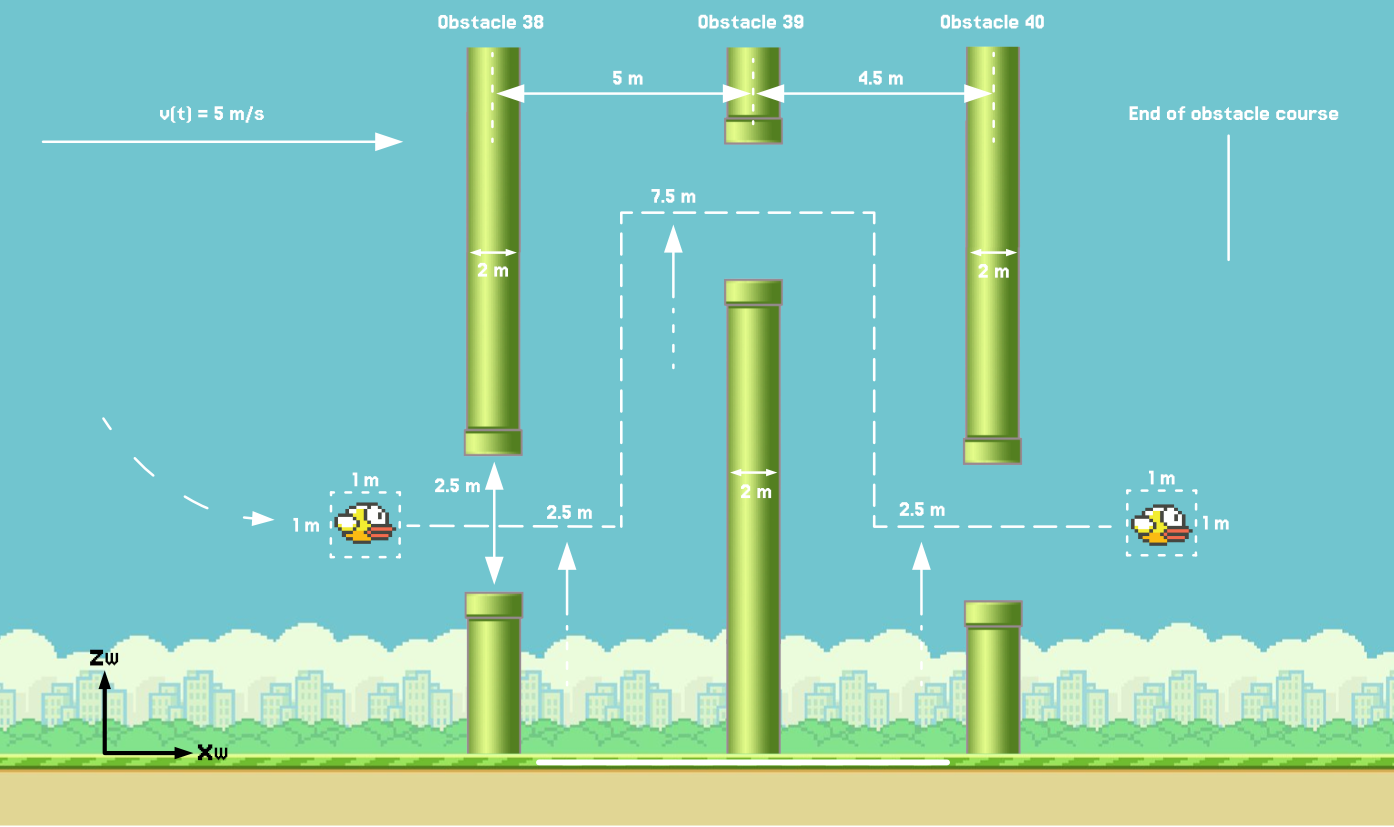

**Figure 2**: Image of Flappy Bird robot attempting to traverse through most challenging upcoming obstacles.

Figure 2 illustrates the most challenging settling time and overshoot requirement when transitioning from *Obstacle 39* to *Obstacle 40*, which implies that if the robot can meet these specifications, then they can meet the less rigorous challenges, as such, this information should be used to define our step response specifications. Note that you also need to take into account the size of your Flappy Bird robot when considering avoiding obstacles.

#### **  Question 4: **Using Figure 2 and the other information provided, determine an appropriate percentage overshoot requirement, $\%OS$, and settling time, $T_s$ that will avoid collision.

*Format: Your submission must be a maximum 1-page PDF and should describe how you determined the above-mentioned performance requirements, with the support of diagrams as appropriate. The work can be handwritten or completed using a document editor (e.g. Word). *

%Code block (if required)


We will make use of the design procedure as outlined in **Chapter 11** and **Chapter 12** of the course notes. Specifically, we will employ frequency-domain specifications that we can ultimately use to shape our loop transfer $L(s)$ via $G(s)$ in **Part 2 **of the Project.

#### **  Question 5: Using your answer from Question 4, **determine an appropriate 2nd-order reference model, $M_A(s)$, that meets the design specifications.

*Format: Your answer should show the necessary working and can be handwritten or mathematically typeset. *

%Code block (if required)


To simplify things, as detailed in **Chapter 11** and **Chapter 12**, we will make use of a *stay-below *boundary to manage our overshoot requirement, and a *stay-above *boundary up to a defined frequency to manage settling time. We should also be cognizant of the different *stay-above *boundary requirements when dealing with Type-0 and Type-1+ controllers (see **Chapter 12** for more information).

#### **  Question 6: Determine the corresponding simplified *****stay-above***** and *****stay-below magnitude response bounds (in dB), as well as the frequency range that these bounds span. The information should be presented in a Bode magnitude response plot, showing that ***$|M_A(j\omega)|_{dB}$ from Question 5 adheres to the prescribed bounds.

*Format: Your answer should be a max one-page document that includes both relevant calculations, as well as the clearly annotated Bode magnitude response plot. Note that you can generate the Bode magnitude response plots using MATLAB.*

%Code block (if required)


#### **  Question 7: Submit your completed Project_Part1.mlx. The file name must be appended with your student number, e.g. Project_Part1_SMTJOH999.slx.** 

*This concludes Part 1 of the Project. You will make use of your answers for Part 1 in Part 2 of the Project.*